# MF4 Can Data Extraction 

First Runs file mf4files which compiles all the data from the MF4 file time. Then it extracts it and puts it into time table so it can be plotted.

clear
% filename = "dev1_11_17_7_14pm.MF4"
load('DEV1_Combined_11_17_test_processed.mat')

Below are the plots for all the data that was extracted from the MF4 file.

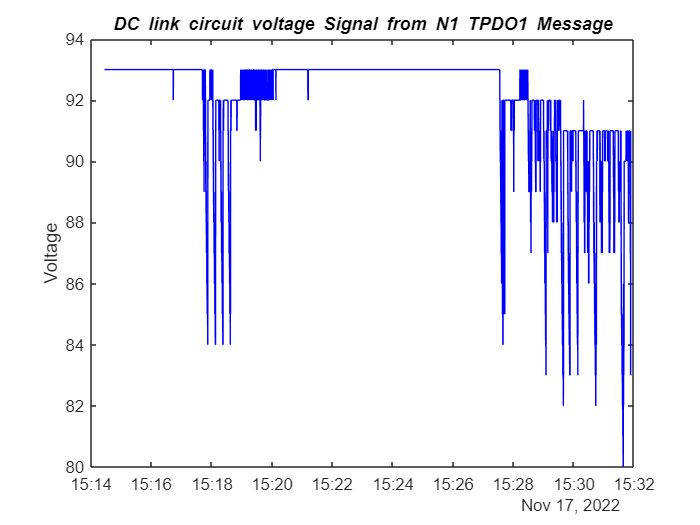

% figure
% % subplot(2, 1, 1)
% plot(N1_TPDO2.Time, N1_TPDO2.Current_Torque_Actual_Value/100, "r")
% title("{\itCurrent Torque Actual Value} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% % xlabel("Timestamp")
% ylabel("Torque")
% subplot(2, 1, 2)
figure
plot(N1_TPDO1.Time, N1_TPDO1.DC_link_circuit_voltage/10, "b")
title("{\itDC link circuit voltage} Signal from {\itN1 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Voltage")

figure
% subplot(2, 1, 1)
% plot(N1_TPDO2.Time, N1_TPDO2.Electrical_angle, "y")
% title("{\itElectrical angle} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
% ylabel("Angle")
% subplot(2, 1, 1)
plot(N1_TPDO0.Time, N1_TPDO0.Velocity_actual_value, "g")
title("{\itVelocity Actual Value} Signal from {\itN1 TPDO0} Message", "FontWeight","bold")
xlabel("Timestamp")

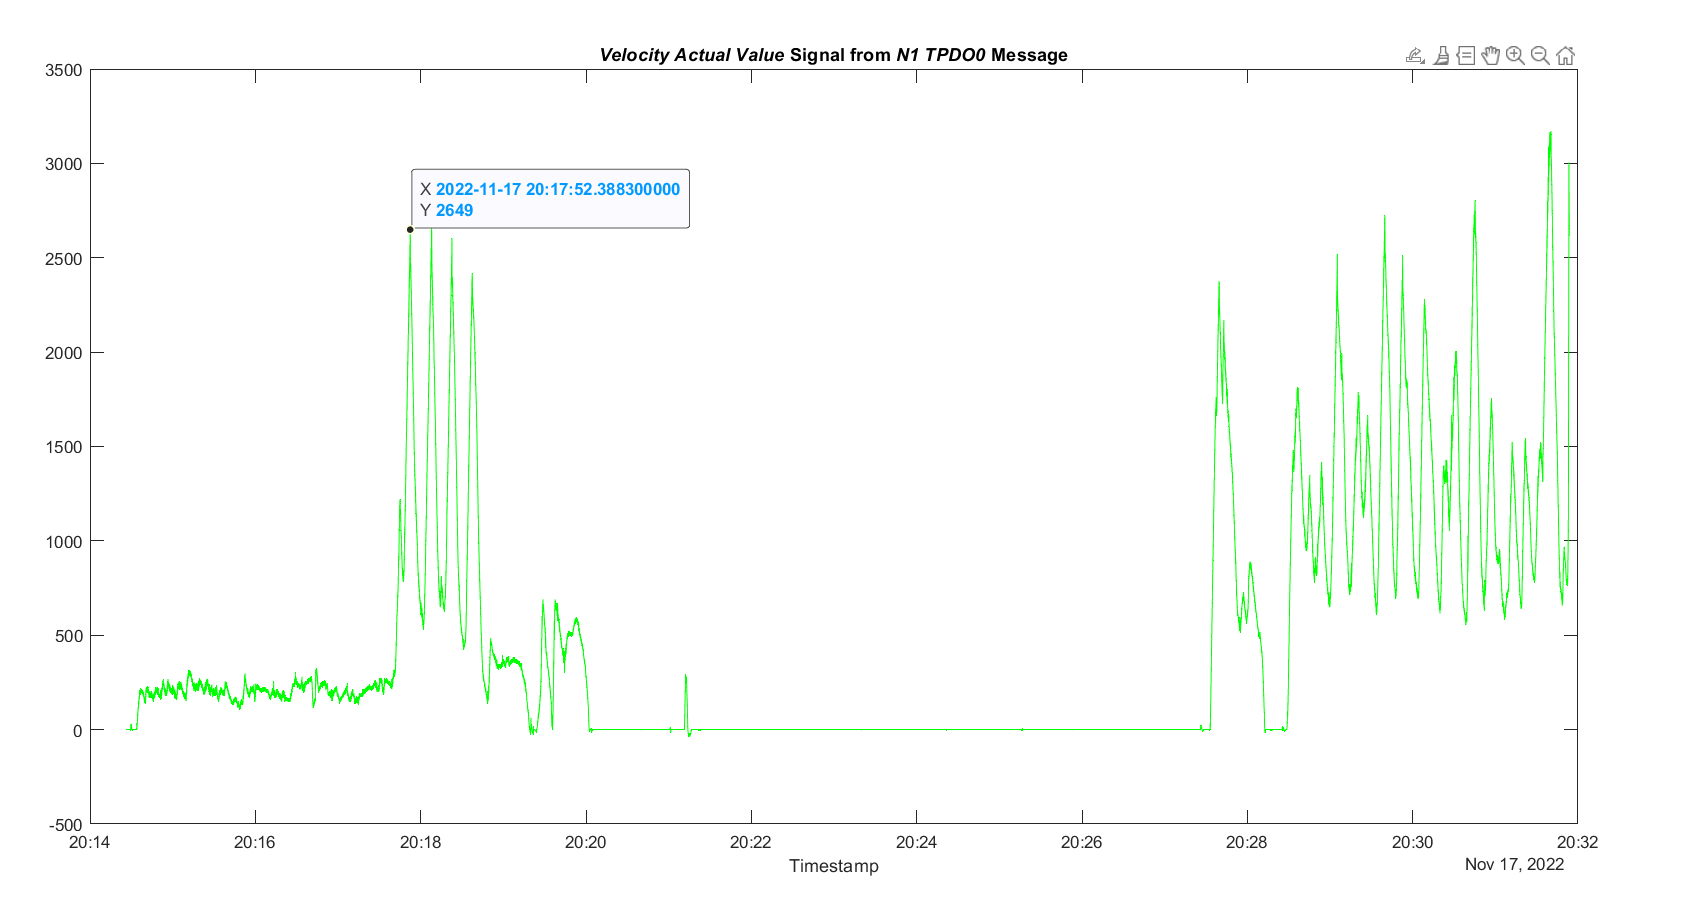

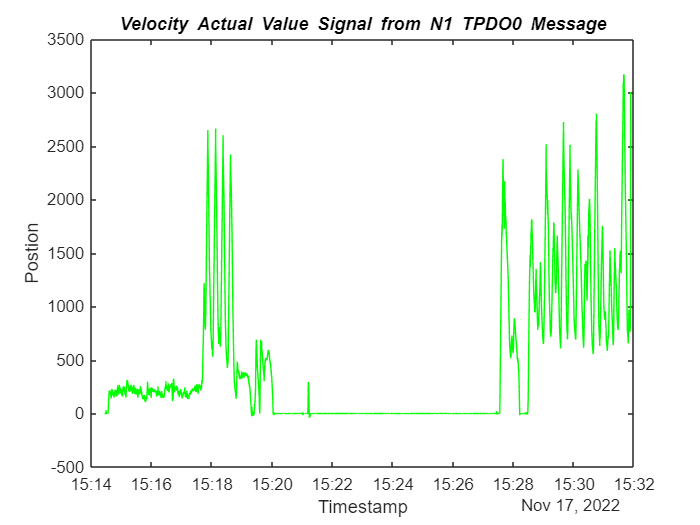

ylabel("Postion")

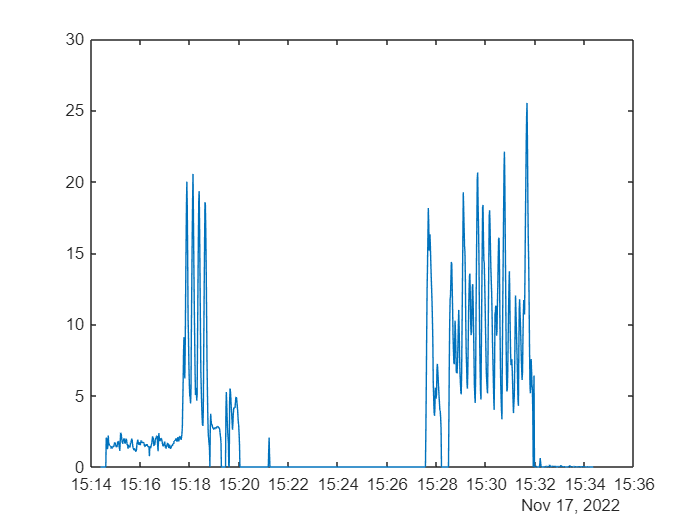


figure
plot(Position.Timestamp, Position.speed)

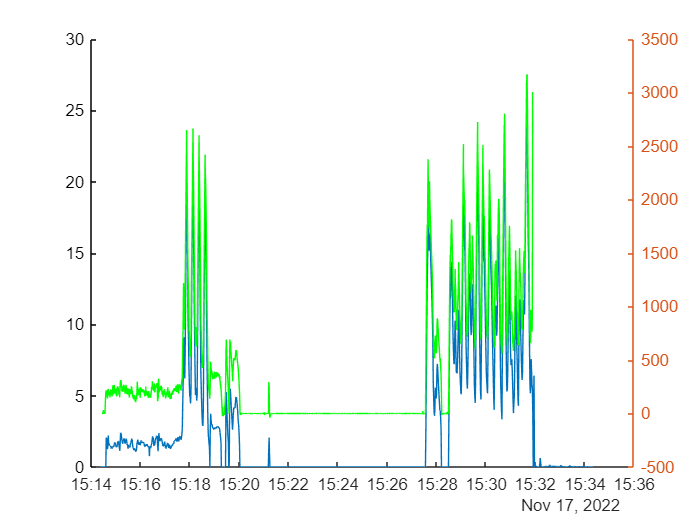

figure
hold on
plot(Position.Timestamp, Position.speed)
yyaxis right
plot(N1_TPDO0.Time, N1_TPDO0.Velocity_actual_value, "g")

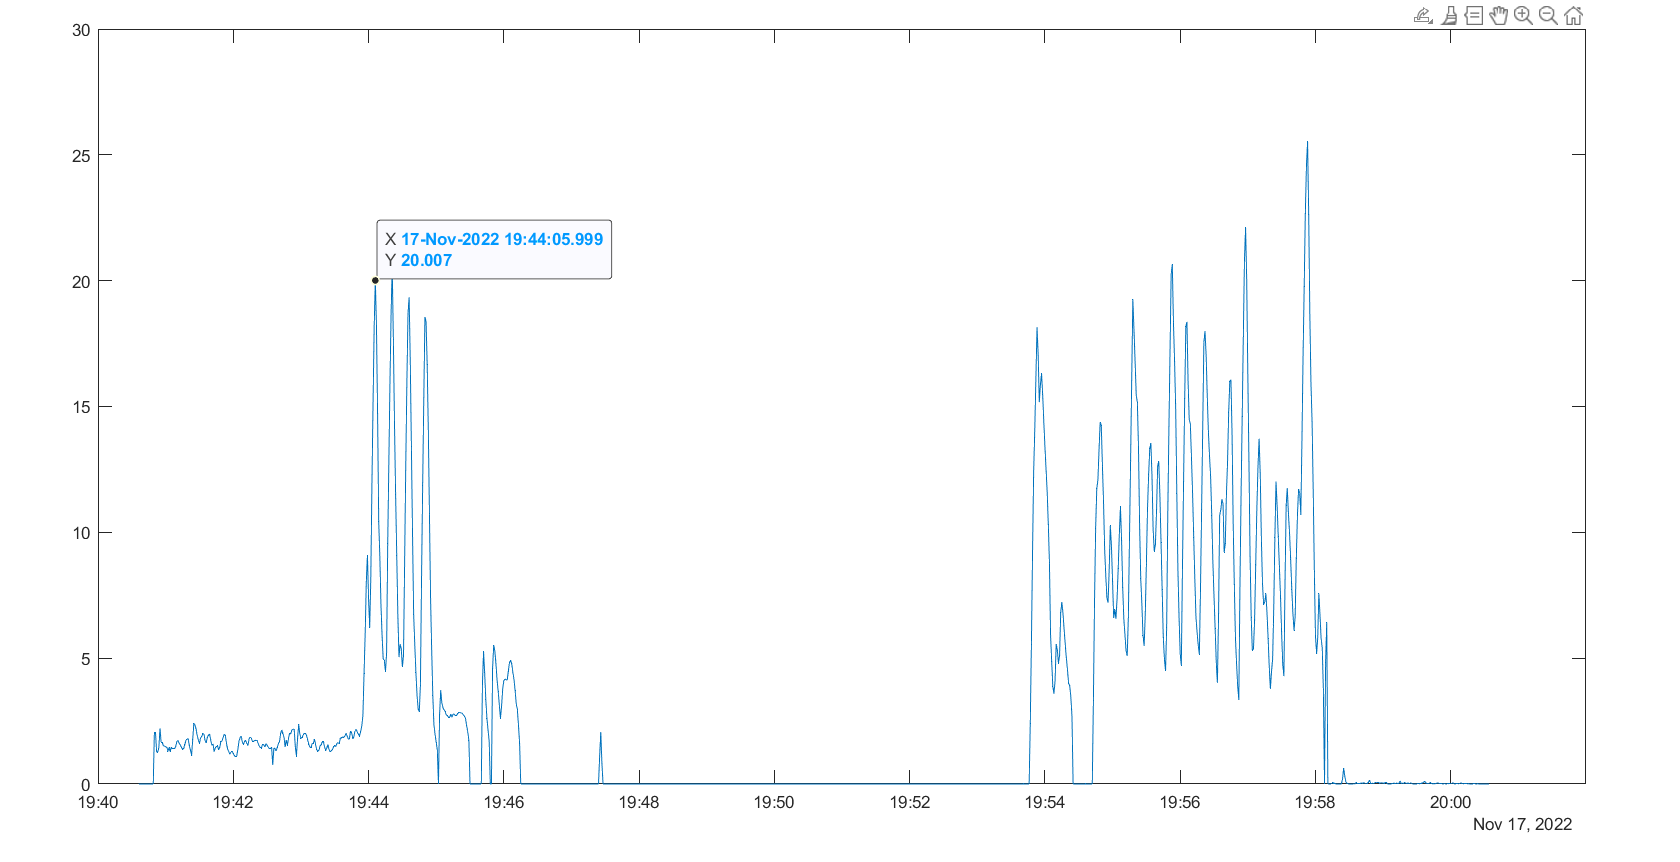

This is all data captured from the Inverter

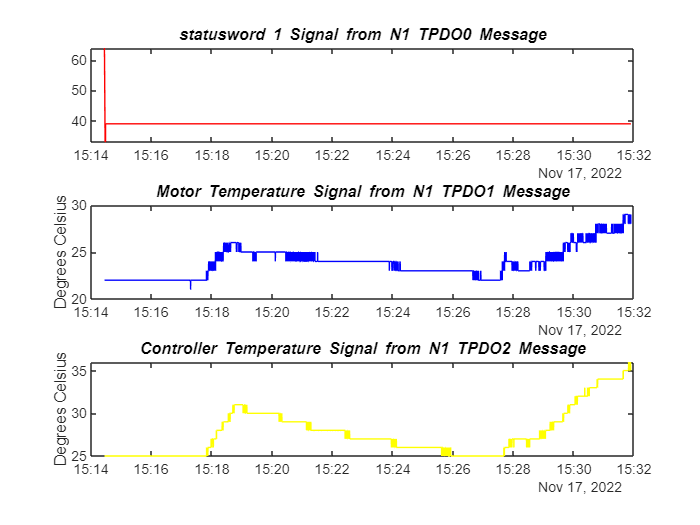

figure
subplot(3, 1, 1)
plot(N1_TPDO0.Time, N1_TPDO0.Statusword, "r")
title("{\itstatusword 1} Signal from {\itN1 TPDO0} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("")

subplot(3, 1, 2)
plot(N1_TPDO1.Time, N1_TPDO1.Motor_temperature, "b")
title("{\itMotor Temperature} Signal from {\itN1 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Degrees Celsius")

subplot(3, 1, 3)
plot(N1_TPDO1.Time, N1_TPDO1.Controller_temperature, "y")
title("{\itController Temperature} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Degrees Celsius")

clear ans canData canDB mdfObj msgTimetable signalTimetable
% clear N10_TPDO0 N10_TPDO1 N10_TPDO2 N10_TPDO3
% save('DEV1_Combined_11_17_test.mat')
